# Comparison of proportional, Lag, Lead and Lead-lag compensator design 

This livescript is a brief manual in support of the app which compares and contrasts mechanistic designs of proportional, lag, lead and lead-lag compensators using simple criteria: i) phase margin; ii) bandwidth; iii) offsets.

As the designs are criteria based, there are no degrees of freedom, the compensator design is fully defined by the criteria. To change behaviour, change the criteria!  Details of these mechanistic designs are fully described in the earlier toolbox files, so will not be repeated: 

***proportional_design_with_bode, proportional_design_phase_margin***, ***lead_design_with_bode,  lag_design_with_bode, lead_design_phase_margin, *** ***lag_design_phase_margin, lead_lag_design_with_bode, lead_lag_design_phase_margin.***

The sole purpose of this app is to compare the designs so that students can get an understanding of the differing roles each compensator plays in achieving desirable behaviour.

Code failures are likely to be linked to unreachable criteria, so the criteria need to be chosen wisely. The app gives out warnings in the top plot where criteria cannot be reached.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Use of the app

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

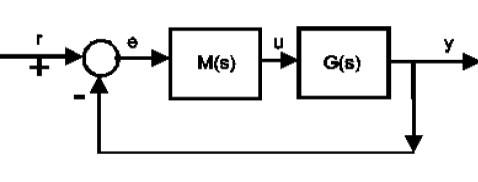

Readers should be familar with the earlier files on proportional, lag, lead and lead-lag design.  You can use the code below to open these files. 

%%%%%%  REMOVE COMMENTS TO RUN THE CODE AND OPEN THE RELEVANT TOOLBOX FILES
% proportional_design_with_bode
% proportional_design_phase_margin    % (app file)
% lead_design_with_bode
% lead_design_phase_margin            % (app file)
% lag_design_with_bode
% lag_design_phase_margin             % (app file)
% lead_lag_design_with_bode 
% lead_lag_design_phase_margin        % (app file)

The app hides the code used to perform the mechanistic designs. If readers would like to see the detailed MATLAB code required, then this is available in the following file:

% lead_lag_design_with_criteria

## 2 Use of the app

A screen dump is shown in the figure 2.1 below. Users can interact as follows:

- Choose the system through the drop down in the yellow box.

- Choose the criteria using the sliders in the green box. The criteria are marked in the plots using dashed green lines.

All the plots and data is updated automatically when the user changes any of the options above.

- The orange box shows the parameters of the lead-lag compensator only as this should meet all 3 criteria.

- The purple boxes show closed-loop data linked to each design in order: Proportional, Lag, Lead and Lead-lag.

- The top plots are the Bode diagrams, including pole/zero positions for each compensator. One would expect the Lag only pole/zero (in blue) to be to the left of the Lead-lag poles and zeros (in red).

- The bottom plots are closed-loop target responses (offsets/errors and inputs) based in steps for systems with no integrator and ramp targets for systems with integrators.

- If the criteria cannot be achieved, error messages appear in the top Bode plot, e.g. see Figure 2.2.

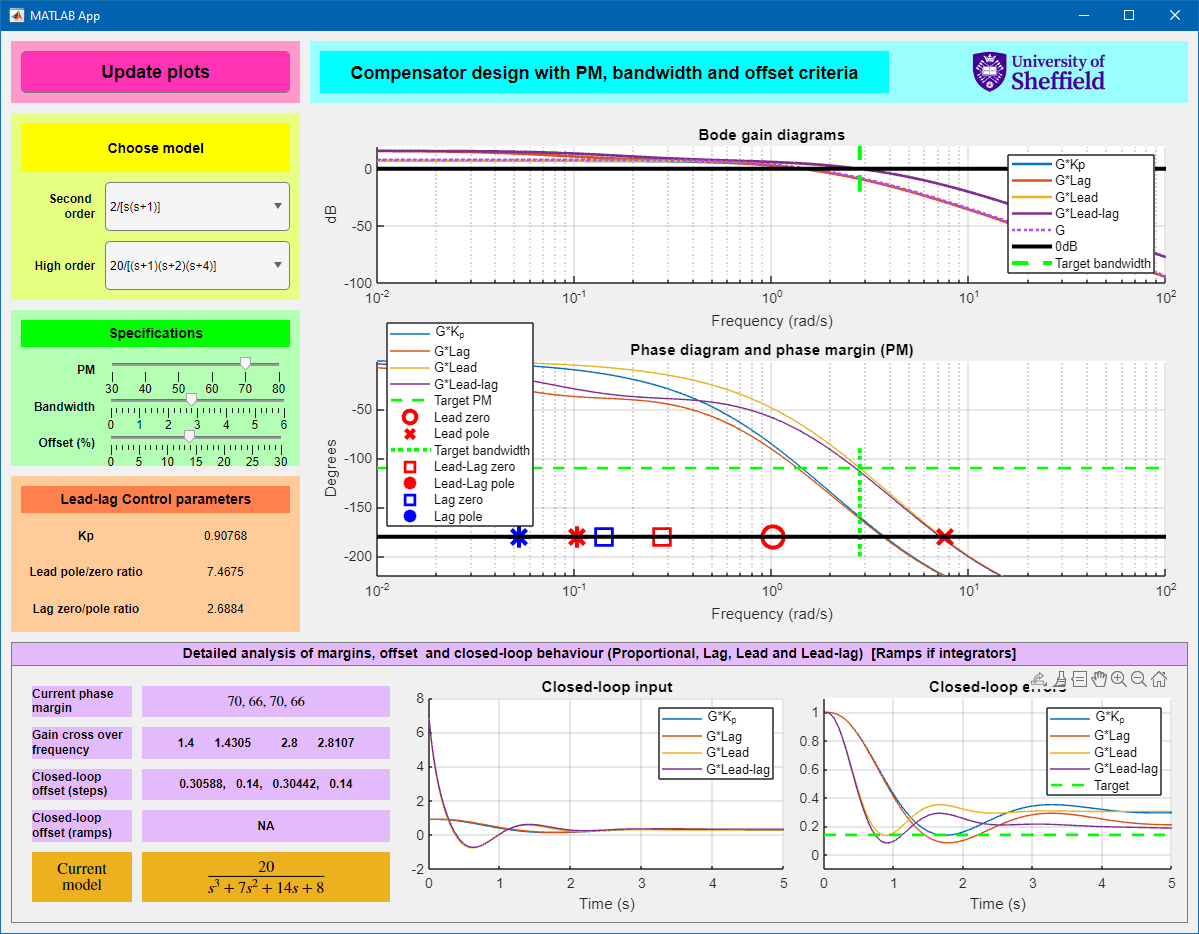

**Figure 2.1**: Screen dump of the lead_lag_design_criteria app.

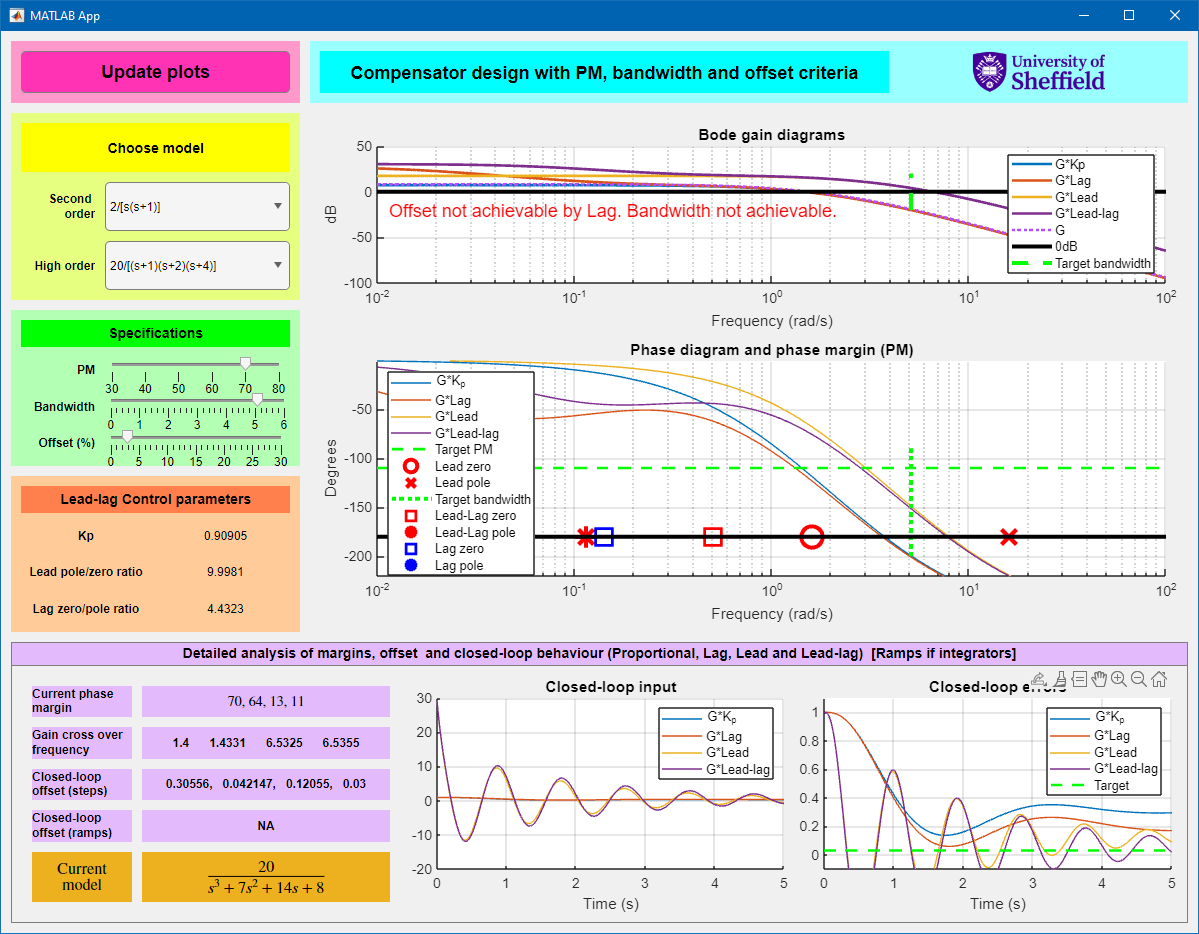

**Figure 2.2**: Illustration of unachievable criteria and error messages.